pod_trav_plant = load("podTrPlant.mat");
pod_trav_plant =frd(pod_trav_plant.o2i1,pod_trav_plant.o2i1x,'FrequencyUnit','Hz');


trav_pod_model ='Pod_trav_plant_linear';
io(1)=linio('Pod_trav_plant_linear/In_engine_current',1,'input');
io(2)=linio('Pod_trav_plant_linear/MS_gyro_velocity',1,'output');
simulation_POD_trav_plant_to_gyro = linearize(trav_pod_model,io);

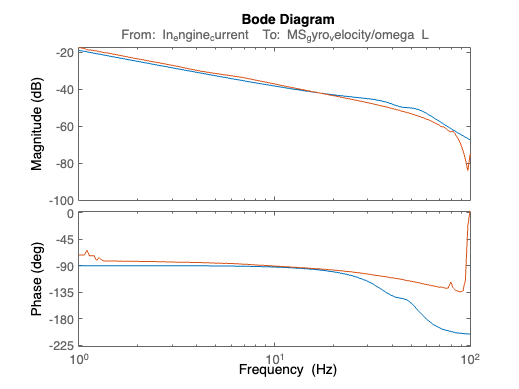

bode(simulation_POD_trav_plant_to_gyro)
hold on
bode(pod_trav_plant)
xlim([1,100])